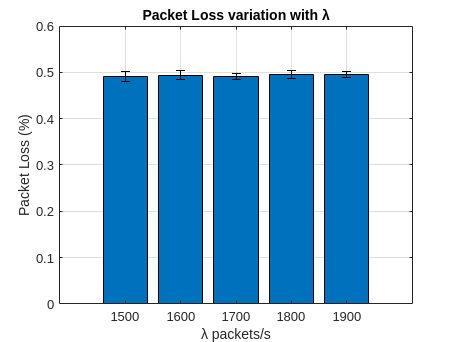

% a
N = 20;

lambda = [1500 1600 1700 1800 1900];

results = zeros(length(lambda), 4, 2);

C = 10;
f = 1000000;
P = 100000;
b = 10^-6;
alfa = 0.1;

for l=1:length(lambda)
    tmp = zeros(4, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i)] = Simulator2(lambda(l), C, f, P, b);
    end

    for i=1:4
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(lambda, results(:, 1, 1));
title("Packet Loss variation with λ");
xlabel("λ packets/s");
ylabel("Packet Loss (%)");
grid on;
hold on;
er = errorbar(lambda, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

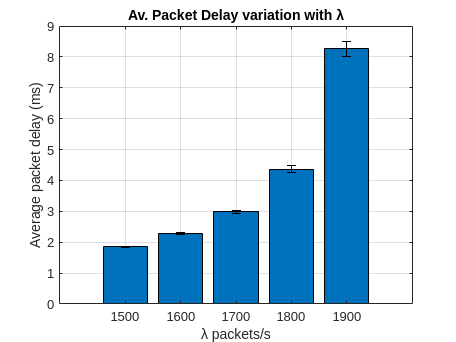


bar(lambda, results(:, 2, 1));
title("Av. Packet Delay variation with λ");
xlabel("λ packets/s");
ylabel("Average packet delay (ms)");
grid on;
hold on;
er = errorbar(lambda, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

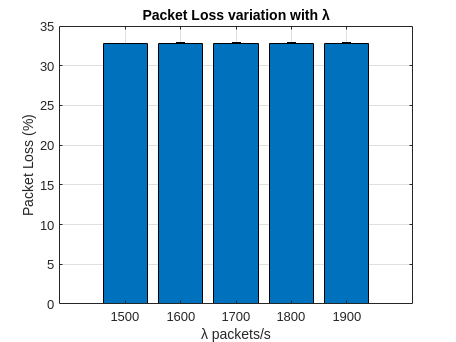

% b

N = 20;

lambda = [1500 1600 1700 1800 1900];

results = zeros(length(lambda), 4, 2);

C = 10;
f = 1000000;
P = 100000;
b = 10^-4;
alfa = 0.1;

for l=1:length(lambda)
    tmp = zeros(4, N);

    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i)] = Simulator2(lambda(l), C, f, P, b);
    end

    for i=1:4
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

bar(lambda, results(:, 1, 1));
title("Packet Loss variation with λ");
xlabel("λ packets/s");
ylabel("Packet Loss (%)");
grid on;
hold on;
er = errorbar(lambda, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

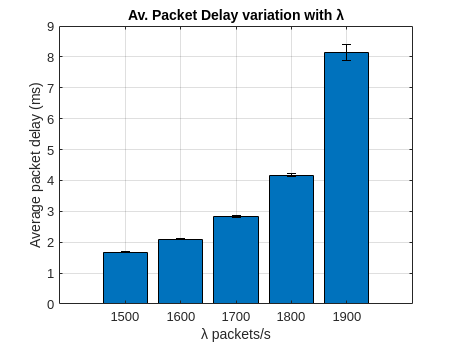


bar(lambda, results(:, 2, 1));
title("Av. Packet Delay variation with λ");
xlabel("λ packets/s");
ylabel("Average packet delay (ms)");
grid on;
hold on;
er = errorbar(lambda, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

% c

b1 = 10^-6;
b2 = 10^-4;

%avgPacketSize = 620.0223;
%avgPacketNoError = (1-b1)^(avgPacketSize*8);
%avgPacketError = 1-avgPacketNoError
%avgPacketNoError = (1-b2)^(avgPacketSize*8);
%avgPacketError = 1-avgPacketNoError
rem = 1 - (0.19 + 0.23 + 0.17);
packetSizes = (64:1518);
packetSizesProbs = ones(1, length(packetSizes)) .* (rem / (length(packetSizes) - 3)); 
packetSizesProbs(1) = 0.19;
packetSizesProbs(110 - 63) = 0.23;
packetSizesProbs(1518 - 63) = 0.17;

packetError = 1-((1-b1).^(packetSizes .*8 ));
sum(packetError .* packetSizesProbs)

ans = 0.0049


packetError = 1-((1-b2).^(packetSizes .*8 ));
sum(packetError .* packetSizesProbs)

ans = 0.3283